%Define constants and Boundary Values
    sigmab = 5.67*10^-8;%Stefan-Boltzmann Constant (W/m^2/K^4)
    G = 6.67430*10^-11; %newton's Gravitation Constant
    kb = 1.380649*10^-23;%Boltzmann Constan (J/K)
    mH = 1.6735575*10^-27; %Mass of Hydrogen atom
    c = 2.998*10^8; %speed of light
    a = 4*sigmab/c; %radiation constant
    gamma = 5/3; %Adiabatic index for Non-relativistic Ideal gas (monoatomic/ionized) 
    X1 = 0.73;%Mass fraction H
    X4 = 0.25;%Mass fraction He 4
    XA = 0.02;%Mass fraction metals
    X14 = 0.01;%Mass fraction Carbon 14
    Rstar = 6.957*10^8; %Radius of the photosphere (m)
    Mstar = 1.998*10^30; %Mass of star(kg)
    Lstar = 3.83*10^26; %Luminosity of star at photosphere (W)
    rhocen = 10^5; %Central density of star (kg/m^3)  
    Tcen = 15*10^6; %Core Temperature of star (K)
    Tstar = (Lstar/(4*pi*sigmab*Rstar^2))^(0.25);
    rhostar = 10^-4;
    ncen = (1+3*X1+0.5*X4)*rhocen/(2*mH);
    Pcen = kb*ncen*Tcen;
    % 
    % %Test range of values
    % 
    % %Pressure as a function of density and temperature
    % P = @(T,rho) (1 + 3*X1 + 0.5*X4).*rho/(2*mH)*kb.*T;
    % Tvar = linspace(10^9,1000,2000000);
    % rhov = [10^-4 10^-3 10^-2 10^-1 10 10^2 10^3 10^4 10^5];
    % P = bsxfun(P,Tvar(:),rhov);
    % figure;
    % loglog(Tvar,P)
    % title('Pressure in a Star')
    % ylabel('Pressure (Pa)')
    % xlabel('Temperature (K)')
    % xlim([5*10^3 10^9])
    % legendTexts = arrayfun(@(rhov) sprintf("\\rho = %E kg/m^3", rhov), rhov, 'uni', 1);
    % legend(legendTexts)
    % set(gca, 'XDir','reverse')
    % grid on
    % 
    % 
    % %k as a function of rho and T
    % 
    %   kes = (0.02)*(1+X1);
    %   kh = @(T,rho) (6*10^-33)*(XA)^(0.5)*rho.^(0.5).*T.^9;
    % ktrans = @(T,rho) (4.3*10^21)*(1+X1)*(XA+0.001)./(1+(T*10^-6)).*rho.*T.^(-3.5);
    % kh = bsxfun(kh,Tvar(:),rhov);
    % ktrans = bsxfun(ktrans,Tvar(:),rhov);
    % 
    % ktotal = ((kes+ktrans).^-1+kh.^-1).^-1;
    % figure;
    % loglog(Tvar,ktotal)
    % title('Opacity Function')
    % ylabel('Opacity (m^2/kg)')
    % xlabel('Temperature (K)')
    % xlim([5*10^3 10^9])
    % legendTexts = arrayfun(@(rho) sprintf('\\rho = %E kg/m^3', rho), rhov, 'uni', 0);
    % legend(legendTexts)
    % 
    % grid on
    % %Energy production
    % 
    % e_pp = @(T,rho)(9.5*10^-13)*X1^2*(rho).^2.*(T/(10^6)).^4;
    % e_CNO = @(T,rho) (4.5*10^-29)*X1*X14.*(rho).^2*(T/(10^6)).^18;
    % 
    % e_ppvar = bsxfun(e_pp,Tvar(:),rhov);
    % e_CNOvar = bsxfun(e_CNO,Tvar(:),rhov);
    % figure
    % loglog(Tvar,e_ppvar)
    % title('Energy Production of P-P Cycle')
    % ylabel('Energy Production Rate (W/kg)')
    % xlabel('Temperature (K)')
    % xlim([5*10^3 10^9])
    % set(gca, 'XDir','reverse')
    % 
    % figure
    % loglog(Tvar,e_CNOvar)
    % title('Energy Production of CNO Cycle')
    % ylabel('Energy Production Rate (W/kg)')
    % xlabel('Temperature (K)')
    % xlim([5*10^3 10^9])
    % set(gca, 'XDir','reverse')
    % 
    % Pvar = linspace(10^4, Pcen, 2000000);
    % rhovar = @(Pvar, T) Pvar*2*mH./(kb.*T*(1+3*X1+0.5*X4));
    % rhovar = bsxfun(rhovar,Pvar, Tvar);
    % figure
    % loglog(Pvar,rhovar)
    % title('Density Vs Pressure')
    % ylabel('Density (kg/m^3)')
    % xlabel('Pressure (Pa)')
    % 
    % figure
    % loglog(Tvar,rhovar)
    % title('Density Vs Temperature')
    % ylabel('Density (kg/m^3')
    % xlabel('Temperature (K)')
    % set(gca, 'XDir','reverse')

    %Define Differential Equations as a function
function dydt = starODE(r, y)
    % m = y(1);
    % P = y(2);
    % Tr = y(3);
    % L = y(4);
    sigmab = 5.67*10^-8;%Stefan-Boltzmann Constant (W/m^2/K^4)
    G = 6.67430*10^-11; %newton's Gravitation Constant
    kb = 1.380649*10^-23;%Boltzmann Constan (J/K)
    mH = 1.6735575*10^-27; %Mass of Hydrogen atom
    c = 2.998*10^8; %speed of light
    a = 4*sigmab/c; %radiation constant
    %gamma = 5/3; %Adiabatic index for Non-relativistic Ideal gas (monoatomic/ionized) 
    X1 = 0.73;%Mass fraction H
    X4 = 0.25;%Mass fraction He 4
    XA = 0.02;%Mass fraction metals
    %X14 = 0.01;%Mass fraction Carbon 14
    rho = y(2)*mH/(kb*y(3))/((1+3*X1+0.5*X4));
    e_pp =  (9.5*10^-13)*X1^2*( rho)^2*y(3)/(10^6)^4;
    kes = (0.02)*(1+X1);
    kh = (6*10^-33)*(XA)^(0.5)*rho^(0.5)*y(3)^9;
    ktrans = (4.3*10^21)*(1+X1)*(XA+0.001)/(1+(y(3)*10^-6))*rho*y(3)^(-3.5);
    ktotal = ((kes+ktrans)^-1+kh^-1)^-1;
    dP = -G*y(1)*rho/(4*pi*r^2);%DE for dP/dr
    dm = 4*pi*r^2*rho; %DE for dm/dr
    dT = -3/(4*a*c)*ktotal*rho*y(4)/(y(3)^3*4*pi*r^2);%DE for radiative heat transport
    %DE for convective heat transport
    %dTc = (gamma-1)/gamma*y(4)/y(2)*-G*y(1)*rho/r^2;
    

    dL = 4*pi*r^2*e_pp; %DE for dL/dr

    dydt = [dm
        dP
        dT
        dL
        rho
        ];
end

%Define intial parameters
delr = 10000;
rspan = linspace(delr,Rstar,1000000);
m0 = 4/3*pi*delr^3*rhocen;
e_ppcen = (9.5*10^-13)*X1^2*(rhocen)^2*(Tcen/(10^6))^4;
L0 = 0;
disp(L0);

     0



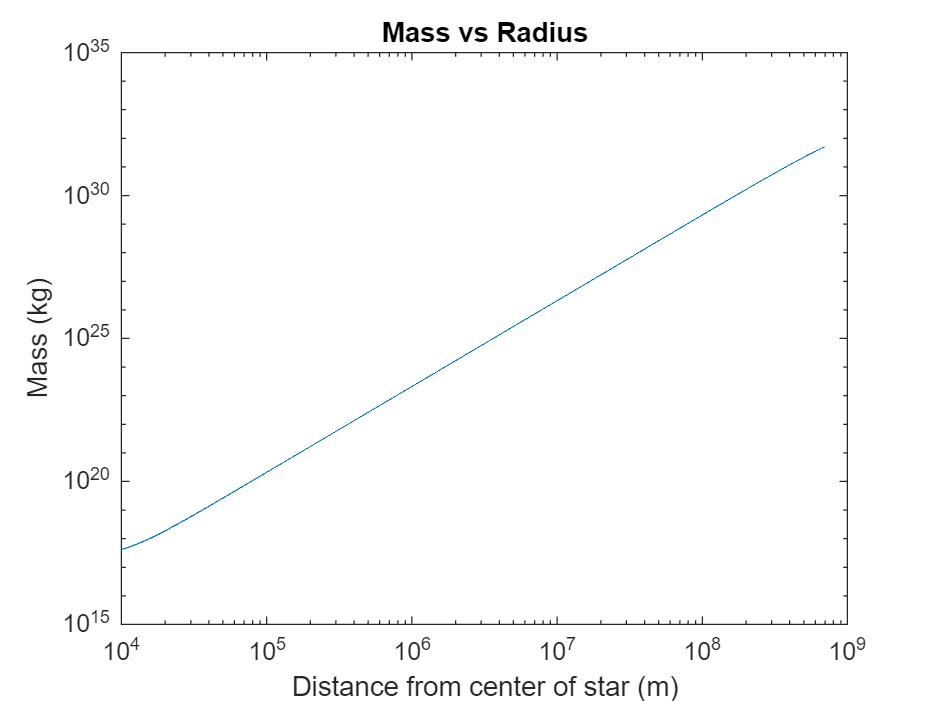

T0 = Tcen;
P0 = Pcen;

y0 = [m0; P0; T0; L0; rhocen];


%Run integrator using Initial Values for Stellar Interior 
[r,y] = ode45(@starODE,rspan,y0);

%Extract integrated variables into arrays
mvec = y(:,1);
Pvec = y(:,2);
Tvec = y(:,3);
Lvec = y(:,4);
rhovec = y(:,5);

%Plot Variables over radius of star
figure
loglog(rspan,mvec)
title('Mass vs Radius')
xlabel('Distance from center of star (m)')
ylabel('Mass (kg)')

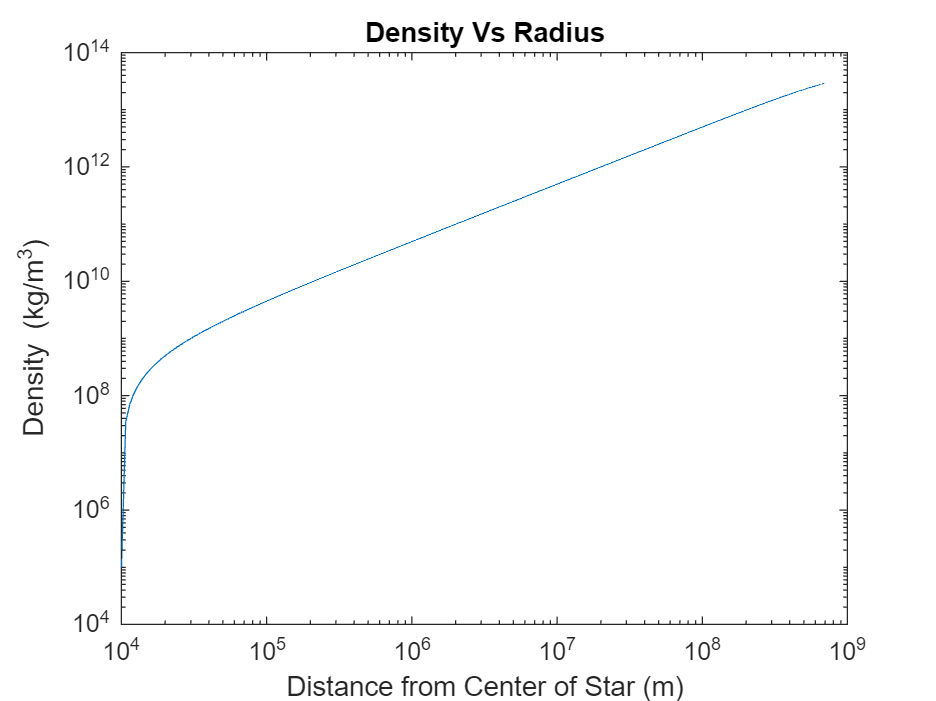

figure
loglog(rspan,rhovec)
title('Density Vs Radius')
xlabel('Distance from Center of Star (m)')
ylabel('Density (kg/m^3)')

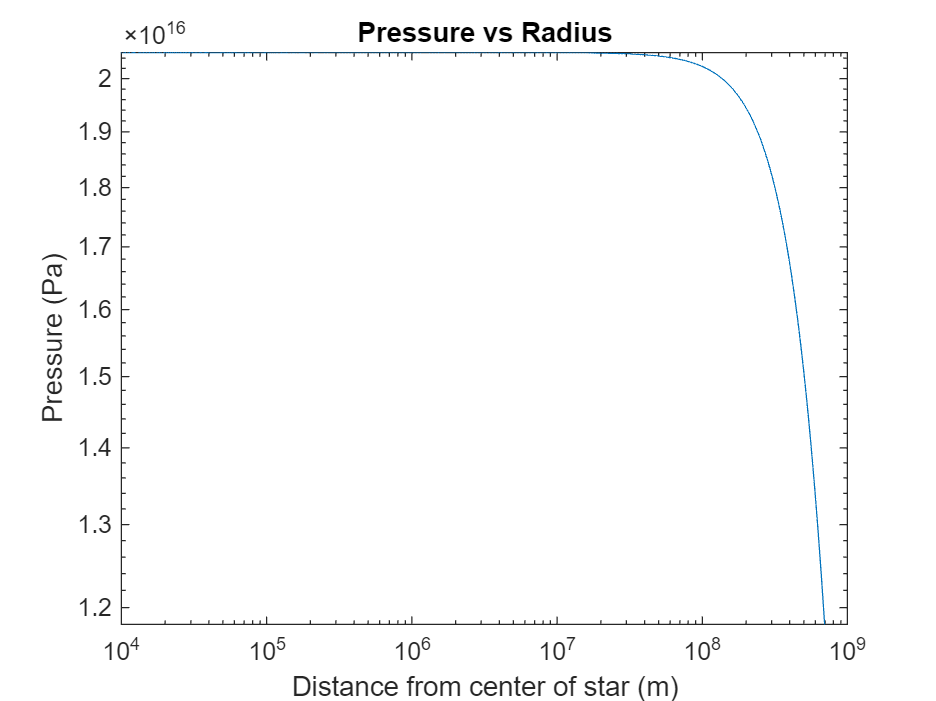

figure
loglog(rspan,Pvec)
title('Pressure vs Radius')
xlabel('Distance from center of star (m)')
ylabel('Pressure (Pa)')

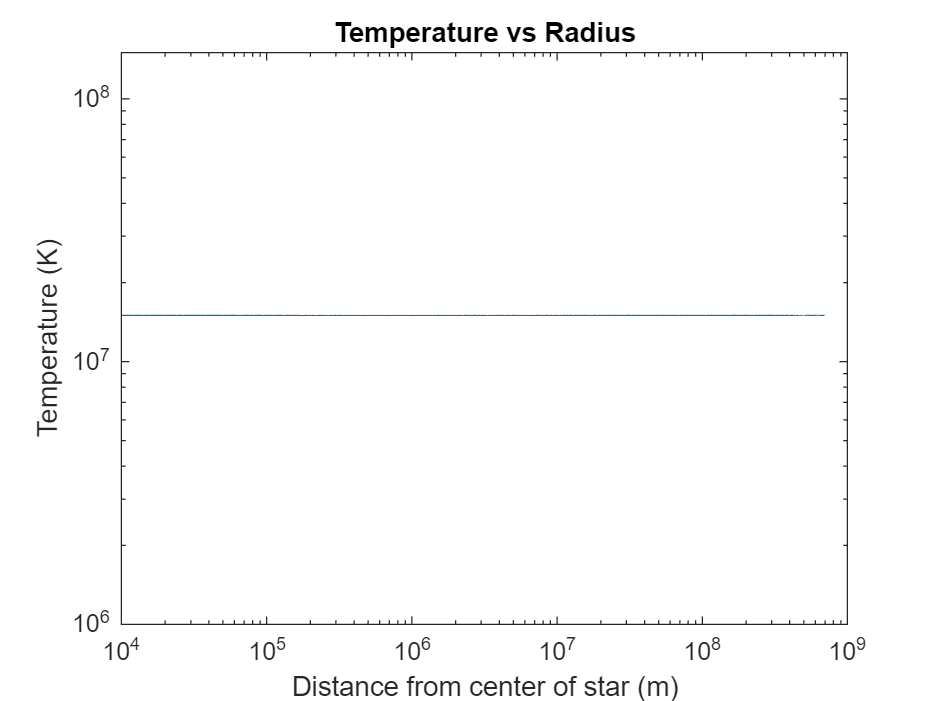

figure
loglog(rspan,Tvec)
title('Temperature vs Radius')
xlabel('Distance from center of star (m)')
ylabel('Temperature (K)')

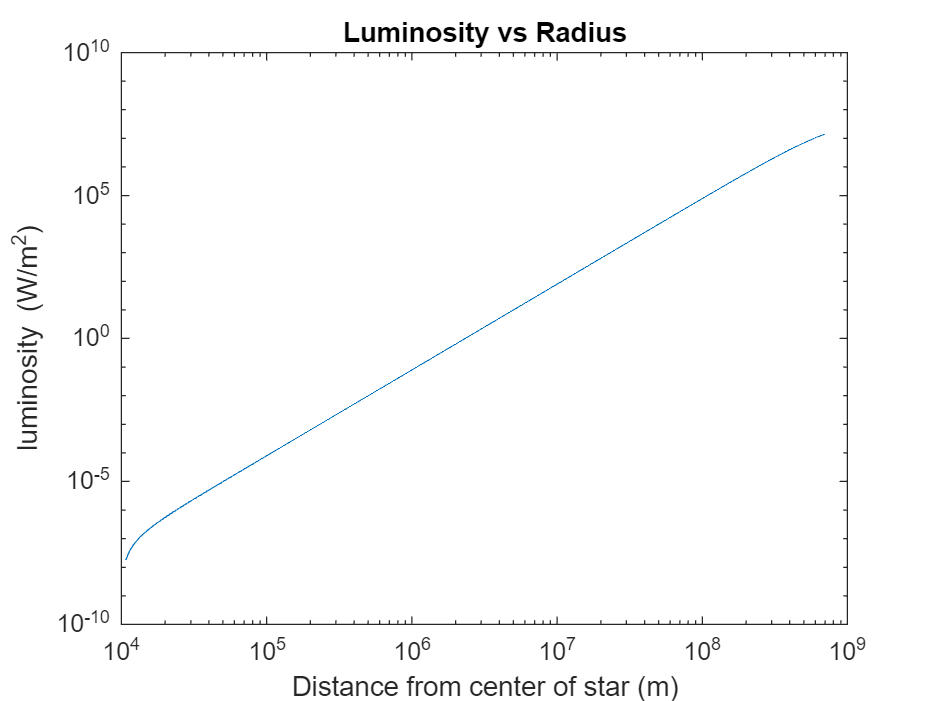

figure
loglog(rspan,Lvec)
title('Luminosity vs Radius')
xlabel('Distance from center of star (m)')
ylabel('luminosity (W/m^2)')


fprintf('Integration Complete')

Integration Complete